load("LAB2_variables.mat")

#### Cinemática Directa RST

La cinemática directa en el RST se hace mediante la función getTransform()

help getTransform

--- help for rigidBodyTree.getTransform ---

rigidBodyTree.getTransform - Get transform between body frames

    This MATLAB function computes the transform that converts points in the bodyname
    frame to the robot base frame, using the specified robot configuration.

    transform = getTransform(robot,configuration,bodyname)
    transform = getTransform(robot,configuration,sourcebody,targetbody)

    See also <a href="https://www.mathworks.com/help/releases/R2020b/robotics/ref/rigidbodytree.geometricjacobian.html">geometricJacobian</a>, <a href="https://www.mathworks.com/help/releases/R2020b/robotics/ref/rigidbodytree.homeconfiguration.html">homeConfiguration</a>, <a href="https://www.mathworks.com/help/releases/R2020b/robotics/ref/rigidbodytree.randomconfiguration.html">randomConfiguration</a>, 
        <a href="https://www.mathworks.com/help/releases/R2020b/robotics/ref/rigidbody.html">rigidBody</a>, <a href="http

Se le pasa como argumento la configuración que se quiere buscar y el marco objetivo, cuando no se especifica un origen se asumen coordenadas globales.

MTH =     0.6421    0.2511    0.7243    0.4811
   -0.6853    0.6114    0.3957    0.2628
   -0.3435   -0.7505    0.5646    1.3041
         0         0         0    1.0000


xyz =     0.4811    0.2628    1.3041


rpy =   -35.0218   46.4107  -21.3542


MTH


MTH =    -0.3338    0.8585   -0.3894    0.0000
   -0.1406   -0.4538   -0.8799   -0.5790
   -0.9321   -0.2389    0.2722    1.1305
         0         0         0    1.0000


xyz =     0.0000   -0.5790    1.1305


rpy =    72.8113  -22.9183 -111.2451


MTH


MTH =    -0.3445    0.6849    0.6420    0.2659
   -0.2316    0.6007   -0.7651   -0.0000
   -0.9098   -0.4123   -0.0483    1.0383
         0         0         0    1.0000


xyz =     0.2659   -0.0000    1.0383


rpy =    93.6100   39.9443 -116.6983


MTH


MTH =    -0.7912   -0.5140    0.3313    0.3532
   -0.5839    0.4738   -0.6592   -0.5501
    0.1818   -0.7150   -0.6750    0.4728
         0         0         0    1.0000


xyz =     0.3532   -0.5501    0.4728


rpy =   135.6781   19.3501  146.9912


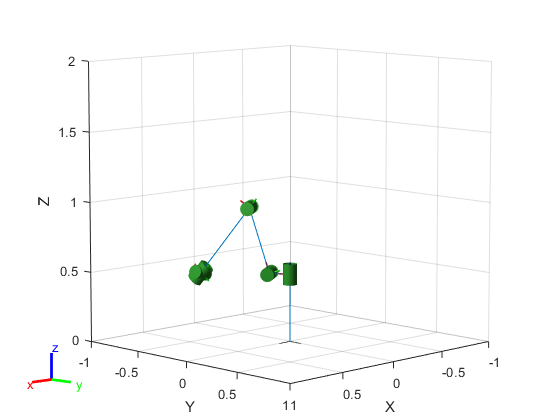

MTH



q=[0.5, 0.2, 0.4, 0.5, 0, 1.5;
    -pi/2 0.3 0 pi/2 0.4 1.2;
    0 1 -0.5 2 1 0.5;
    -1 -0.3 -pi/5 0.4 0.2 1];
q(:,2)=q(:,2)+pi/2;
for i=1:length(q(:,1))
    %disp("MTH")
    %Se calcula la Matriz de transformación homogénea
    MTH=robot.getTransform(q(i,:)',"body6")
    %Se extrae el vector de traslación
    xyz=tform2trvec(MTH)
    %se extraen los angulos roll pitch yaw teniendo en cuenta que el orden
    %´por defecto de la función ZYX
    rpy=rad2deg(tform2eul(MTH,"XYZ"))
    %OPCIONAL mostrar el robot en posición:
    show(robot,q(i,:)','Collisions','on','Visuals','off');
    xlim([-1 1])
    ylim([-1 1])
    zlim([0 2])
    disp("MTH")
end

#### Cinemática Inversa RST

ik = inverseknie

ik=inverseKinematics('RigidBodyTree',robot);
weights = [0.25 0.25 0.25 1 1 1];
initialguess = [0 0 0 0 0 0]';

%
pose_config=[8.15 8.15 5.76 -90 -45 15; 1 1 1 0 30 120; 9 6 3 100 15 30; -3 -2 4 -35 -58 145]

pose_config =     8.1500    8.1500    5.7600  -90.0000  -45.0000   15.0000
    1.0000    1.0000    1.0000         0   30.0000  120.0000
    9.0000    6.0000    3.0000  100.0000   15.0000   30.0000
   -3.0000   -2.0000    4.0000  -35.0000  -58.0000  145.0000


pose_config(:,1:3)=pose_config(:,1:3)./10

pose_config =     0.8150    0.8150    0.5760  -90.0000  -45.0000   15.0000
    0.1000    0.1000    0.1000         0   30.0000  120.0000
    0.9000    0.6000    0.3000  100.0000   15.0000   30.0000
   -0.3000   -0.2000    0.4000  -35.0000  -58.0000  145.0000


configSoln={};
for i=1:4
    rpy_deg=pose_config(i,4:6)
    rpy=deg2rad(rpy_deg)
    rot=eul2rotm(rpy);
    MTHpose = [rot pose_config(i,1:3)'; 0 0 0 1]
    configSoln{i} = rad2deg((ik('body6',MTHpose,weights,initialguess)'));
end

rpy_deg =    -90   -45    15


rpy =    -1.5708   -0.7854    0.2618


MTHpose =     0.0000    0.9659   -0.2588    0.8150
   -0.7071    0.1830    0.6830    0.8150
    0.7071    0.1830    0.6830    0.5760
         0         0         0    1.0000


rpy_deg =      0    30   120


rpy =          0    0.5236    2.0944


MTHpose =     0.8660    0.4330   -0.2500    0.1000
         0   -0.5000   -0.8660    0.1000
   -0.5000    0.7500   -0.4330    0.1000
         0         0         0    1.0000


rpy_deg =    100    15    30


rpy =     1.7453    0.2618    0.5236


MTHpose =    -0.1677   -0.8753    0.4535    0.9000
    0.9513   -0.0229    0.3076    0.6000
   -0.2588    0.4830    0.8365    0.3000
         0         0         0    1.0000


rpy_deg =    -35   -58   145


rpy =    -0.6109   -1.0123    2.5307


MTHpose =     0.4341   -0.8683    0.2401   -0.3000
   -0.3039   -0.3920   -0.8683   -0.2000
    0.8480    0.3039   -0.4341    0.4000
         0         0         0    1.0000
